Problem 1: Solve Stokes

%%%%%%%%%%%%%%%%%%%%%%%%
%%% Define Constants %%%
%%%%%%%%%%%%%%%%%%%%%%%%

% Domain in x (periodic)
x_start = 0;
x_end = 1;

% Domain in y (walls)
y_start = 0;
y_end = 1;

% viscocity
mu = 1;

% Number of cells
Nx = 50;    % in x
Ny = Nx;    % in y

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%% Method of Manufactured Solutions %%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

U_an = @(x, y) sin(2.*pi.*y) .* sin(2.*pi.*x);
V_an = @(x, y) -3.5 + cos(2.*pi.*x) .* (cos(2.*pi.*y) - 1);
P_an = @(x, y) sin(2.*pi.*y) .* cos(2.*pi.*x);

f = @(x,y) (-8*pi^2 + 2*pi) .* sin(2.*pi.*y) .* sin(2.*pi.*x);
g = @(x,y) (-8*pi^2 - 2*pi) .* cos(2.*pi.*y) .* cos(2.*pi.*x) + (4.*pi.^2 .* cos(2.*pi.*x));


%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%% Grid Initialization %%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Grid Spacings
dx = (x_end-x_start) / Nx;
dy = (y_end-y_start) / Ny;

% P at cell centers
x_P = (linspace(x_start, Nx-1+x_start, Nx) + 0.5) .* dx;
y_P = (linspace(y_start, Ny-1+y_start, Ny) + 0.5) .* dy;

% U on east/west faces
x_U = (linspace(x_start, Nx-1+x_start, Nx)) .* dx;
y_U = y_P;

% V on north/south faces
x_V = x_P;
y_V = (linspace(y_start+1, Ny+y_start-1, Ny+1)) .* dy;

% Number of unknowns
nU = Nx * Ny;           % we know right BC (periodic)
nV = Nx * (Ny + 1);     % we know top and bottom BCs
nP = Nx * Ny;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%% Build Operators and RHS %%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Operators as Sparse Matrices       [ADD HERE]
val = [];
row = [];
col = [];

b = [];

bu = [];
bu2 = [];
% Lu
for j = 1:Ny
    for i = 1:Nx
        k = i + (j-1)*Nx;
        if j == 1
            if i == 1           % top left corner
                row = [row, k]; col = [col, k]; val = [val, -5/(dx^2)];
                row = [row, k]; col = [col, k+1]; val = [val, 1/(dx^2)];
                row = [row, k]; col = [col, k+Nx-2]; val = [val, 1/(dx^2)];
                row = [row, k]; col = [col, k+Nx]; val = [val, 1/(dx^2)];
            elseif i == Nx     % top right corner  
                row = [row, k]; col = [col, k]; val = [val, -5/(dx^2)];
                row = [row, k]; col = [col, k-Nx+2]; val = [val, 1/(dx^2)];
                row = [row, k]; col = [col, k-1]; val = [val, 1/(dx^2)];
                row = [row, k]; col = [col, k+Nx]; val = [val, 1/(dx^2)];
            else                % top BC
                row = [row, k]; col = [col, k]; val = [val, -5/(dx^2)];
                row = [row, k]; col = [col, k-1]; val = [val, 1/(dx^2)];
                row = [row, k]; col = [col, k+1]; val = [val, 1/(dx^2)];
                row = [row, k]; col = [col, k+Nx]; val = [val, 1/(dx^2)];
            end
            b = [b, 0];
        elseif j == Ny
            if i == 1           % bottom left corner
                row = [row, k]; col = [col, k]; val = [val, -5/(dx^2)];
                row = [row, k]; col = [col, k+1]; val = [val, 1/(dx^2)];
                row = [row, k]; col = [col, k+Nx-2]; val = [val, 1/(dx^2)];
                row = [row, k]; col = [col, k-Nx]; val = [val, 1/(dx^2)];
            elseif i == Nx    % bottom right corner
                row = [row, k]; col = [col, k]; val = [val, -5/(dx^2)];
                row = [row, k]; col = [col, k-Nx+2]; val = [val, 1/(dx^2)];
                row = [row, k]; col = [col, k-1]; val = [val, 1/(dx^2)];
                row = [row, k]; col = [col, k-Nx]; val = [val, 1/(dx^2)];
            else                % bottom BC
                row = [row, k]; col = [col, k]; val = [val, -5/(dx^2)];
                row = [row, k]; col = [col, k+1]; val = [val, 1/(dx^2)];
                row = [row, k]; col = [col, k-1]; val = [val, 1/(dx^2)];
                row = [row, k]; col = [col, k-Nx]; val = [val, 1/(dx^2)];
            end
            b = [b, 0];
        else
            if i == 1           % left BC
                row = [row, k]; col = [col, k]; val = [val, -4/(dx^2)];
                row = [row, k]; col = [col, k+1]; val = [val, 1/(dx^2)];
                row = [row, k]; col = [col, k+Nx-2]; val = [val, 1/(dx^2)];
                row = [row, k]; col = [col, k+Nx]; val = [val, 1/(dx^2)];
                row = [row, k]; col = [col, k-Nx]; val = [val, 1/(dx^2)];
            elseif i == Nx    % right BC
                row = [row, k]; col = [col, k]; val = [val, -4/(dx^2)];
                row = [row, k]; col = [col, k-Nx+2]; val = [val, 1/(dx^2)];
                row = [row, k]; col = [col, k-1]; val = [val, 1/(dx^2)];
                row = [row, k]; col = [col, k+Nx]; val = [val, 1/(dx^2)];
                row = [row, k]; col = [col, k-Nx]; val = [val, 1/(dx^2)];
            else                % internal points
                row = [row, k]; col = [col, k]; val = [val, -4/(dx^2)];
                row = [row, k]; col = [col, k+1]; val = [val, 1/(dx^2)];
                row = [row, k]; col = [col, k-1]; val = [val, 1/(dx^2)];
                row = [row, k]; col = [col, k+Nx]; val = [val, 1/(dx^2)];
                row = [row, k]; col = [col, k-Nx]; val = [val, 1/(dx^2)];
            end
            b = [b, f((i-1),(j+(1/2)))];
        end
    end
end

Lu = sparse(row, col, val);

% Lv
val = [];
row = [];
col = [];

bv = [];

for j = 1:Ny+1
    for i = 1:Nx
        k = i + (j-1)*Nx;
        if j == 1 || j == Ny+1      % top/bottom rows
            row = [row, k]; col = [col, k]; val = [val, 1];
            b = [b, -3.5];
        else
            if i == 1               % left BC
                row = [row, k]; col = [col, k]; val = [val, -4/(dx^2)];
                row = [row, k]; col = [col, k+1]; val = [val, 1/(dx^2)];
                row = [row, k]; col = [col, k+Nx-2]; val = [val, 1/(dx^2)];
                row = [row, k]; col = [col, k-Nx]; val = [val, 1/(dx^2)];
                row = [row, k]; col = [col, k+Nx]; val = [val, 1/(dx^2)];
            elseif i == Nx          % right BC
                row = [row, k]; col = [col, k]; val = [val, -4/(dx^2)];
                row = [row, k]; col = [col, k-Nx+2]; val = [val, 1/(dx^2)];
                row = [row, k]; col = [col, k-1]; val = [val, 1/(dx^2)];
                row = [row, k]; col = [col, k-Nx]; val = [val, 1/(dx^2)];
                row = [row, k]; col = [col, k+Nx]; val = [val, 1/(dx^2)];
            else                    % internal points
                row = [row, k]; col = [col, k]; val = [val, -4/(dx^2)];
                row = [row, k]; col = [col, k+1]; val = [val, 1/(dx^2)];
                row = [row, k]; col = [col, k-1]; val = [val, 1/(dx^2)];
                row = [row, k]; col = [col, k-Nx]; val = [val, 1/(dx^2)];
                row = [row, k]; col = [col, k+Nx]; val = [val, 1/(dx^2)];
            end
            b = [b, g((i-(1/2)), (j))];
        end
    end 
end

Lv = sparse(row, col, val);

% Gx
val = [];
row = [];
col = [];

for j = 1:Ny
    for i = 1:Nx
        k = i + (j-1)*Nx;
        if j == 1       % left BC
            if i == 1
                row = [row, k]; col = [col, k+1]; val = [val, -1/(2*dx)];
                row = [row, k]; col = [col, k]; val = [val, 0];
                row = [row, k]; col = [col, k+Nx-2]; val = [val, 1/(2*dx)];
            else
                row = [row, k+1]; col = [col, k]; val = [val, -1/(2*dx)];
                row = [row, k]; col = [col, k]; val = [val, 0];
                row = [row, k-1]; col = [col, k]; val = [val, 1/(2*dx)];
            end
        elseif j == Ny  % right BC
            if i == Nx
                row = [row, k]; col = [col, k-Nx+2]; val = [val, -1/(2*dx)];
                row = [row, k]; col = [col, k]; val = [val, 0];
                row = [row, k]; col = [col, k-1]; val = [val, 1/(2*dx)];
            else
                row = [row, k+1]; col = [col, k]; val = [val, -1/(2*dx)];
                row = [row, k]; col = [col, k]; val = [val, 0];
                row = [row, k-1]; col = [col, k]; val = [val, 1/(2*dx)];
            end
        else            % internal points
            row = [row, k]; col = [col, k+1]; val = [val, -1/(2*dx)];
            row = [row, k]; col = [col, k]; val = [val, 0];
            row = [row, k]; col = [col, k-1]; val = [val, 1/(2*dx)];
        end
    end
end

Gx = sparse(row, col, val);

% Gy
val = [];
row = [];
col = [];

for j = 1:Ny+1
    for i = 1:Nx
        k = i + ((j-1)*Nx);
        if j == 1       % left BC
            if i == 1
                row = [row, k+1]; col = [col, k]; val = [val, -1/(2*dx)];
                row = [row, k]; col = [col, k]; val = [val, 0];
                row = [row, k+Ny-1]; col = [col, k]; val = [val, 1/(2*dx)];
            else
                row = [row, k+1]; col = [col, k]; val = [val, -1/(2*dx)];
                row = [row, k]; col = [col, k]; val = [val, 0];
                row = [row, k-1]; col = [col, k]; val = [val, 1/(2*dx)];
            end
        elseif j == Ny+1 % right BC
            row = [row, k]; col = [col, k-Nx]; val = [val, 0];
        else            % internal points
            row = [row, k+1]; col = [col, k]; val = [val, -1/(2*dx)];
            row = [row, k]; col = [col, k]; val = [val, 0];
            row = [row, k-1]; col = [col, k]; val = [val, 1/(2*dx)];
        end
    end
end

Gy = sparse(row, col, val);

% Dx
val = [];
row = [];
col = [];

bp = [];

for j = 1:Ny
    for i = 1:Nx
        k = i + (j-1)*Nx;
        if j == 1
            if i == 1
                row = [row, k]; col = [col, k+1]; val = [val, 1/(2*dx)];
                row = [row, k]; col = [col, k]; val = [val, 0];
                row = [row, k]; col = [col, k+Nx-2]; val = [val, -1/(2*dx)];
            else
                row = [row, k]; col = [col, k+1]; val = [val, 1/(2*dx)];
                row = [row, k]; col = [col, k]; val = [val, 0];
                row = [row, k]; col = [col, k-1]; val = [val, -1/(2*dx)];
            end
        elseif j == Ny
            if i == Nx
                row = [row, k]; col = [col, k-Nx+2]; val = [val, 1/(2*dx)];
                row = [row, k]; col = [col, k]; val = [val, 0];
                row = [row, k]; col = [col, k-1]; val = [val, -1/(2*dx)];
            else
                row = [row, k]; col = [col, k+1]; val = [val, 1/(2*dx)];
                row = [row, k]; col = [col, k]; val = [val, 0];
                row = [row, k]; col = [col, k-1]; val = [val, -1/(2*dx)];
            end
        else
            row = [row, k]; col = [col, k+1]; val = [val, 1/(2*dx)];
            row = [row, k]; col = [col, k]; val = [val, 0];
            row = [row, k]; col = [col, k-1]; val = [val, -1/(2*dx)];
        end
        b = [b, 0];
    end
end

Dx = sparse(row, col, val);

% Dy
val = [];
row = [];
col = [];

for j = 1:Ny
    for i = 1:Nx+1
        k = j + ((i-1)*Nx);
        if i == 1
            if j == 1
                row = [row, k]; col = [col, k+1]; val = [val, -1/(2*dx)];
                row = [row, k]; col = [col, k]; val = [val, 0];
                row = [row, k]; col = [col, k+Nx-1]; val = [val, 1/(2*dx)];
            else
                row = [row, k]; col = [col, k+1]; val = [val, -1/(2*dx)];
                row = [row, k]; col = [col, k]; val = [val, 0];
                row = [row, k]; col = [col, k-1]; val = [val, 1/(2*dx)];
            end
        elseif i == Nx+1
                row = [row, k-Ny]; col = [col, k]; val = [val, 0];
        else
            row = [row, k]; col = [col, k+1]; val = [val, -1/(2*dx)];
            row = [row, k]; col = [col, k]; val = [val, 0];
            row = [row, k]; col = [col, k-1]; val = [val, 1/(2*dx)];
        end
    end
end

Dy = sparse(row, col, val);

% Matrix Construction
A = [blkdiag([mu.*Lu, zeros(nU, nV), -Gx]); ...
     blkdiag([zeros(nV,nU), mu.*Lv, -Gy]); ...
     blkdiag([Dx, Dy, zeros(nP, nP)])];

rhs = b';

%%%%%%%%%%%%%
%%% Solve %%%
%%%%%%%%%%%%%

sol = A \ rhs;

% Put U, V, and P on their grids
U = reshape(sol(1:nU), [Ny, Nx]);
V = reshape(sol(nU+1:nU+nV), [Ny+1, Nx]);
P = reshape(sol(nU+nV+1:nU+nV+nP), [Ny, Nx]);

% Zero-Mean Pressure
P = P - mean(P);

% Interpolate U and V to Cell Centers
U_num = [];
for i = 1:Nx
    U_row = [];
    for j = 1:Ny
        if i == Nx
            U_row = [U_row, 0.5 * (U(j,i) + U(j, 1))];
        else
            U_row = [U_row, 0.5 * (U(j,i) + U(j, i+1))];
        end
    end
    U_num = [U_num; U_row];
end
        
V_num = [];
for j = 1:Ny
    V_row = [];
    for i = 1:Nx
        if j == Ny
            V_row = [V_row, 0.5 * (U(j,i) + U(1, i))];
        else
            V_row = [V_row, 0.5 * (U(j,i) + U(j+1, i))];
        end
    end
    V_num = [V_num; V_row];
end

%%%%%%%%%%%%
%%% Plot %%%
%%%%%%%%%%%%
x = linspace(0, 1, Nx+1);
y = linspace(0, 1, Ny+1);

y =          0    0.0200    0.0400    0.0600    0.0800    0.1000    0.1200    0.1400    0.1600    0.1800    0.2000    0.2200    0.2400    0.2600    0.2800    0.3000    0.3200    0.3400    0.3600    0.3800    0.4000    0.4200    0.4400    0.4600    0.4800    0.5000    0.5200    0.5400    0.5600    0.5800    0.6000    0.6200    0.6400    0.6600    0.6800    0.7000    0.7200    0.7400    0.7600    0.7800    0.8000    0.8200    0.8400    0.8600    0.8800    0.9000    0.9200    0.9400    0.9600    0.9800


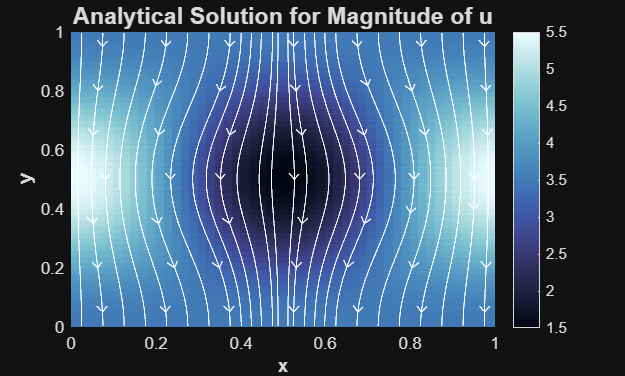



% plot analytical solution
U_a = [];
V_a = [];
for j = 1:Ny+1
    U_ac = [];
    V_ac = [];
    for i = 1:Nx+1
        U_ij = U_an(x(i), y(j));
        V_ij = V_an(x(i), y(j));
        U_ac = [U_ac, U_ij];
        V_ac = [V_ac, V_ij];
    end
    U_a = [U_a; U_ac];
    V_a = [V_a; V_ac];
end

[X, Y] = meshgrid(x, y);

hold on
pcolor(x, y, sqrt(U_a.^2 + V_a.^2), 'EdgeColor','interp')
colormap(slanCM('ice'))
colorbar()
s = streamslice(X, Y, U_a, V_a);
set(s, 'Color', 'w')

% title, labels, and legend
xlabel('x', 'FontWeight','bold')
ylabel('y','FontWeight','bold')
title('Analytical Solution for Magnitude of u','FontSize',14,'FontWeight','bold')

hold off